# Generate Snellen E

## Housekeeping

clear
close all

export_images = true;
gamma_correct = false;


## Make base image

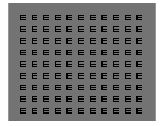

canvas_size = [912, 1140];                                   % x,y pixels
microns_per_pixel = 3.37;                                     % microns per pixel
pixels_per_micron = 1/microns_per_pixel;
num_orientations = 4;


letter_size_microns = 150;
letter_size_px = ceil(letter_size_microns*pixels_per_micron);

if gamma_correct
    background = 0.45 ^ (1/2.2);
else
    background = 0.45;
end


E_matrix = zeros([5,5]);
E_matrix(2,2:5) = background;
E_matrix(4,2:5) = background;

E_matrix_scaled = imresize(E_matrix,...               % scale noise matrix
        [letter_size_px, letter_size_px], 'method', 'nearest');

E_matrix_scaled = repmat(E_matrix_scaled,1,1,3);
image_set = zeros(canvas_size(1), canvas_size(2), 3*num_orientations, 'uint8');
filename = strcat('tumblingE.mat');

for ii = 1:num_orientations
    full_screen = ones(canvas_size)*background;
    full_screen = repmat(full_screen, 1,1,3);
    E_matrix_scaled = rot90(E_matrix_scaled);
    for i = 2:floor(canvas_size(2)/letter_size_px)-1
        for j = 2:floor(canvas_size(1)/letter_size_px)-1
            if mod(i,2) == 0 || mod(j,2) == 0
                continue
            else
                full_screen(j*letter_size_px-letter_size_px+1:j*letter_size_px, i*letter_size_px-letter_size_px+1:i*letter_size_px, :) = E_matrix_scaled;
            end
        end
    end
    imshow(full_screen);
    image_set(:,:,(ii*3)-2:ii*3) = uint8(full_screen*255);
end


if export_images
        save(filename, "image_set");
end

